# Analyse temporelle et fréquentielle avec la Symbolic Mathtoolbox

close all;
F=[100 200 400]

F =    100   200   400


A=[3 1 5]

A =      3     1     5


syms t      				% symbolic toolbox
x= sin(2*pi*F*t) 		    % continuous signal

$$x = \left(\begin{array}{ccc} \sin\left(200\,\pi \,t\right) & \sin\left(400\,\pi \,t\right) & \sin\left(800\,\pi \,t\right) \end{array}\right)$$

sig=sum(A.*x)

$$sig = 3\,\sin\left(200\,\pi \,t\right)+\sin\left(400\,\pi \,t\right)+5\,\sin\left(800\,\pi \,t\right)$$

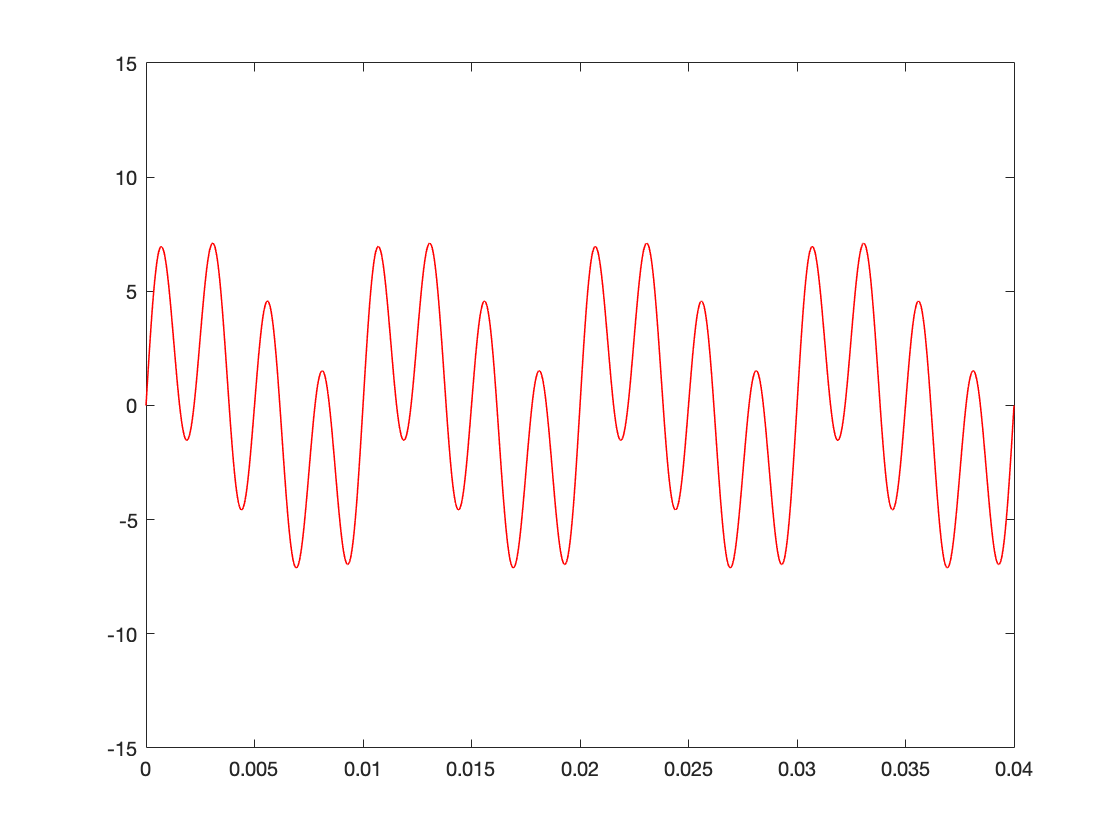

figure;
nexttile;
fplot(sig,[0 1/64*4],'r','LineWidth',0.75);
axis([ 0 1/100*4 -15 15]);



% spectre du signal
syms  f w
% Continuous Fourier Transform
% Method 1:
X = fourier(sig,t,w);
X = subs(X,w,2*pi*f);
X = simplify(X)

$$X = -3\,\pi \,\left(\frac{\delta (f-100)}{2\,\pi }-\frac{\delta (f+100)}{2\,\pi }\right)\,\mathrm{i}-\pi \,\left(\frac{\delta (f-200)}{2\,\pi }-\frac{\delta (f+200)}{2\,\pi }\right)\,\mathrm{i}-5\,\pi \,\left(\frac{\delta (f-400)}{2\,\pi }-\frac{\delta (f+400)}{2\,\pi }\right)\,\mathrm{i}$$